clear
close all

# **Power analysis for studying variance**

**Shinya M and Takiyama K**

"Guidelines for balancing the number of trials and the number of subjects to ensure the statistical power to detect variability – Implication for gait studies"

**J Biomech.** 2024 Feb 15:165:111995. DOI: [10.1016/j.jbiomech.2024.111995](https://doi.org/10.1016/j.jbiomech.2024.111995)

## **Comparing variance between conditions: a paired-sample design**

Let us consider a within-subject comparison design. An example of such a research is that investigates the difference in step variability during walking between the intact and paretic sides in stroke patients.

## **Assumption and theory**

We assume that data in each trial follows normal distribution specific to each condition. 

Because the paired t tests and Wilcoxon signed-rank tests may overrate the influence of participants with large variances, we consider to take the ratio of unbiased variances of two conditions for each participant, which is related to the F distribution.


$$\frac{{s_2 }^2 /{\sigma_2 }^2 }{{s_1 }^2 /{\sigma_1 }^2 }\sim F_{{\left(n_2 -1,n_1 -1\right)}}$$


or,


$$\frac{{s_2 }^2 }{{s_1 }^2 }\sim F_{{\left(n_2 -1,n_1 -1\right)}} \frac{{\sigma_2 }^2 }{{\sigma_1 }^2 }$$


If the ratio of unbiased variances is greater (or less) than 1, it indicates that the variability is larger (or smaller) under condition 2.

As the ratio is not symmetric around 1, we took the logarithm of the ratio of variances between conditions $\mathrm{log}\left(\frac{{s_2 }^2 }{{s_1 }^2 }\right)$, and we compared this value to 0. When the degrees of freedom are equal, distribution of the logarithm of the F-distribution is symmetrical around 0 and approximately normal, allowing for the use of a parametric one-sample t-test.

## **Simulation parameters**

We calculate the probability 1-β of correctly detecting the difference in variance between groups for given numbers of trials and participants. As an alternative hypothesis, we assumed the ratio of the population variances for 2 conditions.

% number of trials, number of subjects
nTrial1 = 100 ;
nTrial2 = 60 ;
nSubject = 15 ;

% parametric or non-parametric test?
    % Note that the distribution of log(s2^2/s1^2) is almost normal especially when n1 = n2.
    % Thus, ttest should be good to test the difference between the groups.
    % If n1 and n2 are quite different from each other, it might be safe to use the signrank test.
    % Check the figure(1) 
method = 'ttest' ; 
% method = 'signrank' ; 
    

% ratio of population variances for 2 conditions
sigmaSquaredRatio = 1.21 ;

% number of simulation
nSim = 10000 ; 



## **Simulation - a single case**

This is a simulation of one experiment to compare the sample variance between two conditions (i.e., a paired-sample design).Whether we have a significant difference or not is stochastically determined.

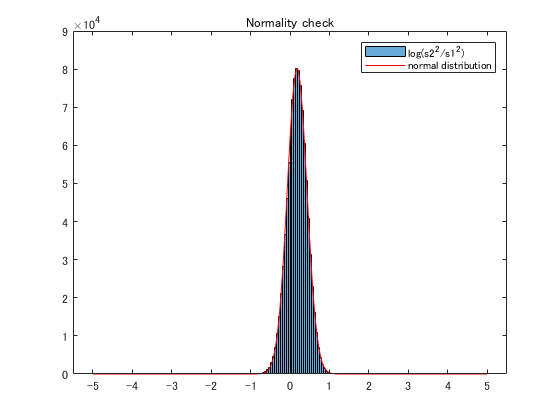

% simulate an experiment

% Create tables of inverse cumulative distribution function of F distribution
sizeTable = 1000000 ;
pp = linspace(1/sizeTable, 1-1/sizeTable, sizeTable)' ;

distTable = finv(pp, nTrial2-1, nTrial1-1) ; 

% Create tables of ratio of sample variances between conditions
randData = distTable * sigmaSquaredRatio ;

% Take a log of the ratio
logRandData = log(randData) ;

% Comparing the log(s2^2/s1^2) to the normal distribution
figure(1)
w = 20 ;
histogram(logRandData, [-5:1/w:5]) ; hold on
mm = mean(logRandData) ; ss = std(logRandData) ;
xx = [-5:1/100:5] ; yy = normpdf(xx, mm, ss)*(sizeTable/w) ;
plot(xx, yy, 'r-')
legend({'log(s2^2/s1^2)', 'normal distribution'})
title('Normality check')

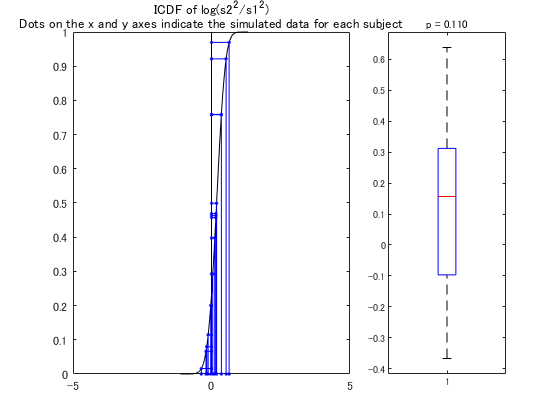


% Simulate one experiment
randInd = randi(sizeTable, nSubject, 1) ;
simData = randData(randInd) ;
logSimData = logRandData(randInd) ;

% statistical test to compare between the conditions
if isequal(method,'ttest')
    [h, p] = ttest(logSimData) ;
elseif isequal(method, 'signrank')
    [p, h] = signrank(logSimData) ;
else
    disp('''method'' should be ttest or signrank')
    return
end

% visualize the simulation
figure(2) ; subplot(1,3,1:2) ;
plot(logRandData, pp, 'k') ; hold on
plot([0,0], [0,1], 'k-') ;
for ii = 1:length(randInd)
    xx = [0, logRandData(randInd(ii)), logRandData(randInd(ii))] ;
    yy = [pp(randInd(ii)), pp(randInd(ii)), 0] ;
    plot(xx, yy, 'b.-')
end
set(gca, 'xlim', [-5,5]) ;
title({'ICDF of log(s2^2/s1^2)';
       'Dots on the x and y axes indicate the simulated data for each subject'})

subplot(1,3,3) ;
boxplot(logSimData)
title(sprintf('p = %0.3f', p))

## **Simulation - a post hoc power analysis**

We will repeat many simulations to count the cases where we have a significant difference. The proportion of the case over the total number of simulations can be regarded as statistical power $1-\beta$.

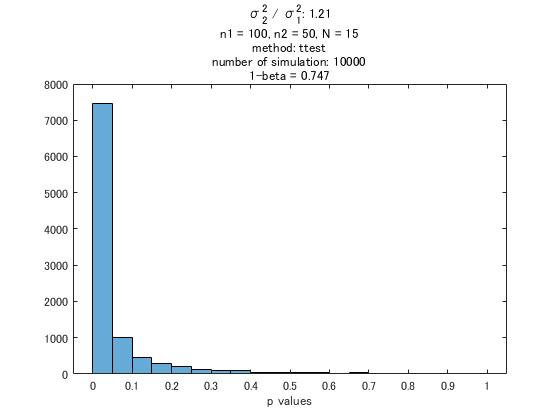



tic ; % just for monitoring the computational load 

% create simulated data (i.e., log(s2^2/s1^2) )
randInd = randi(sizeTable, nSubject, nSim) ;
simData = randData(randInd) ;
logSimData = log(simData) ;

% statistical test
for iSim = 1:nSim
    
    if isequal(method,'ttest')
        [h, p] = ttest(logSimData(:,iSim)) ; 
    elseif isequal(method, 'signrank')
        [p, h] = signrank(logSimData(:,iSim)) ;
    else
        disp('''method'' should be ttest or ranksum')
        return
    end
    
    pArray(iSim) = p ;
    hArray(iSim) = h ;
end

% visulization of the calculated statical power
figure ;
histogram(pArray, 20)
statisticalPower = sum(hArray) / nSim ;
titleText = {sprintf('σ_2^2 / σ_1^2: %0.2f', sigmaSquaredRatio) ;...
             sprintf('n1 = %d, n2 = %d, N = %d', nTrial1, nTrial2, nSubject);...
             ['method: ', method];...
             sprintf('number of simulation: %d', nSim) ;...
             sprintf('1-beta = %0.3f', statisticalPower)} ;
title(titleText) ;
xlabel('p values')


toc

経過時間は 1.014664 秒です。
